### Filtro Gaussiano

Il filtro gaussiano è un filtro di **sfocatura **ma assegna un peso maggiore ai pixel centrali, seguendo la forma della distribuzione gaussiana.

I = rgb2gray(imread("imgs/lena.png"));

% Dimensione del kernel e sigma
dim_k = [21,21];
sigma = 2.5;

% Creiamo il kernel gaussiano
kernel = fspecial("gaussian", dim_k,sigma);

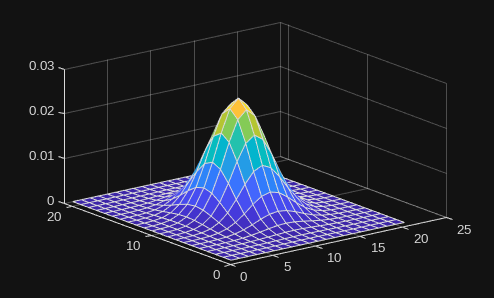

surf(kernel); % plotting del kernel

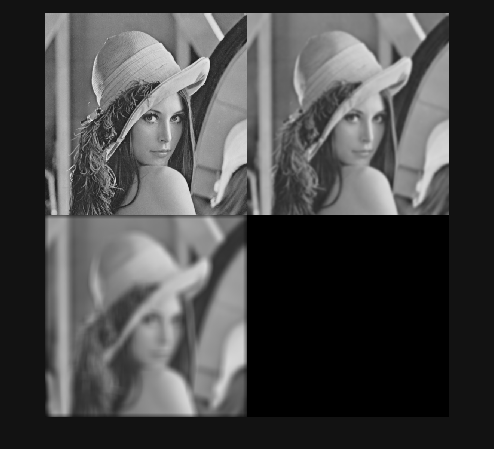

img_gauss = imfilter(I,kernel,"replicate");
K_conv = fspecial("average",[21,21]);
img_avg = conv2(single(I), K_conv, "same");
montage({I,img_gauss,uint8(img_avg)}); % differenza tra filtro di convoluzione e gaussiano

Il filtro gaussiano è un filtro a variabili separabili. È un **filtro passa-banda (frequenze medie)** 

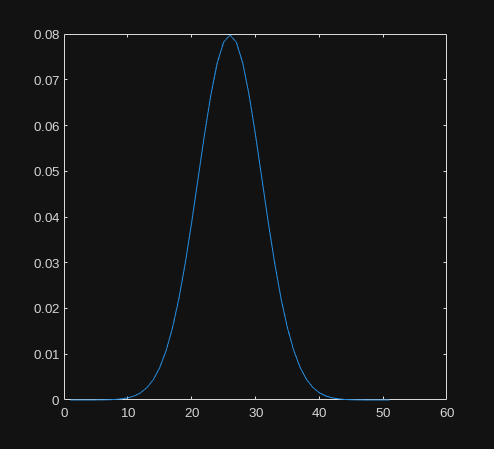

% Usiamo la separabilità delle variabili
t = fspecial("gaussian",[1,51],5.0); % kernel unidimensionale gaussiano
a = t' * t; % Prodotto tensoriale.
plot(t);

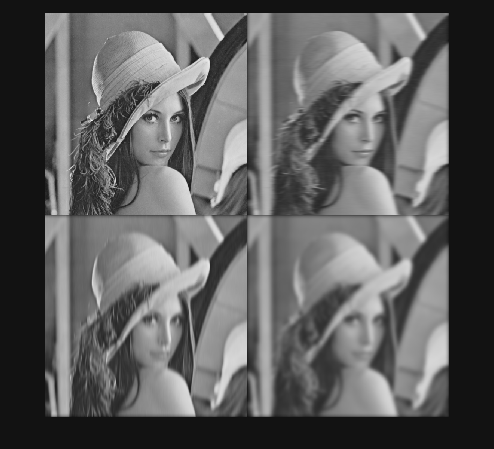

% Convoluzione con kernel separabile
gx = uint8(conv2(I,t,"same"));
gy = uint8(conv2(I,t',"same"));
gxy = uint8(conv2(gx,t',"same"));
montage({I,gx,gy,gxy});

**Anche qui è possibile usare una LUT per i prodotti precalcolati.**